### **Create DataSet objects**

clc;
warning("off","all")

% make data object
[obj_arr, mset_arr] = make_objs();

### **Select and plot the chosen dataset; set Y, M**

close all;
epica_data = obj_arr{1};    % 1 = CO2, 2 = CH4, 3 = d18O
% plot(epica_data.X,epica_data.Y);

% set number of "years" and "months" to divide data into
Y = 200;
M = 50;
m = 2;


### **Run findanf function & plot a(k), N(k), f(tau) over multiple m values + Woosok estimate**

close all;

% run findanf_epica for range of m-values
n = 49;
m_arr = linspace(n,Y-4,(Y-4)/n);

for m=m_arr
    
    disp(m);
    
    [a_final,N,f,~] = findanf_epica(epica_data,Y,M,m);
    figure(1);
    hold on;
    plot(a_final);
    
    figure(2);
    hold on;
    plot(N);
    
    figure(3);
    hold on;
    plot(f);
end

    49



    98



   147



   196



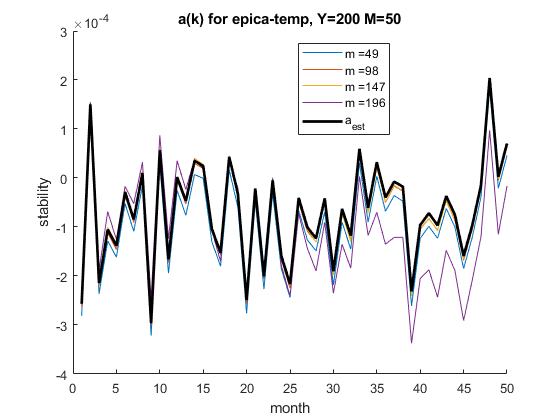



    


% run findanf Woosok estimate version
[a_est,~] = findanf_est(epica_data,Y,M);

% plot a-values in fig. 1
figure(1);
hold on;
plot(a_est,'LineWidth',2,'Color','black');
legend_cell = strcat('m = ', string(num2cell(m_arr)));
legend_cell{end+1} = 'a_{est}';
legend(legend_cell,'Location','Best');
xlabel("month");
ylabel("stability");
title(sprintf("a(k) for %s, Y=%d M=%d", epica_data.data_name, Y, M));
saveas(gcf,sprintf("%s_a_%d-%d.jpeg",epica_data.data_name,Y,M));

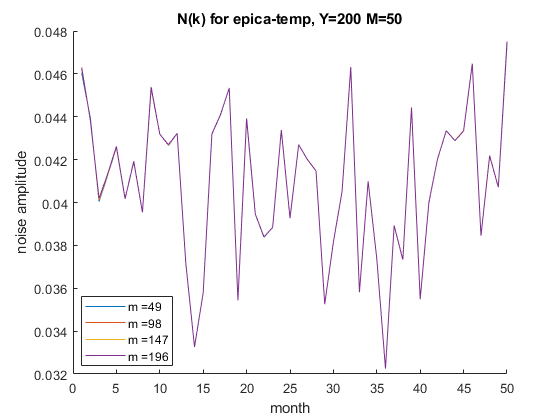


% plot N-values in fig. 2
figure(2);
hold on;
% plot(N_est,'LineWidth',2,'Color','black');
legend_cell = strcat('m = ', string(num2cell(m_arr)));
% legend_cell{end+1} = 'N_{est}';
legend(legend_cell,'Location','Best');
xlabel("month");
ylabel("noise amplitude");
title(sprintf("N(k) for %s, Y=%d M=%d", epica_data.data_name, Y, M));
saveas(gcf,sprintf("%s_N_%d-%d.jpeg",epica_data.data_name,Y,M));


% plot f-values in fig. 3
figure(3);
xlabel("year");
ylabel("backbone forcing");
title(sprintf("f(tau) for %s, Y=%d M=%d",epica_data.data_name,Y,M));
legend_cell = strcat('m = ', string(num2cell(m_arr)));
legend_cell{end+1} = 'a_{est}';
legend(legend_cell);

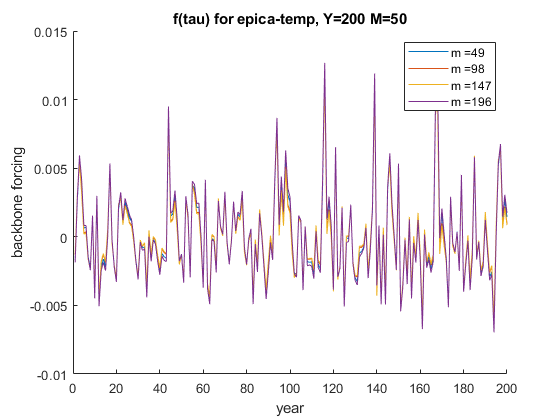

saveas(gcf,sprintf("%s_f_%d-%d.jpeg",epica_data.data_name,Y,M));

### **Estimate response timescale & year offset m for B(k)**

[a_est,N_est] = findanf_est(epica_data,Y,M);

M_length = range(epica_data.X) / (Y*M)

M_length = 159.6750

int_aest = sum(a_est) / M_length;
T_aest = 1 / abs(int_aest);
num_M_est = T_aest / M_length;
num_Y_est = num_M_est / M

num_Y_est = 59.4371

Y_est_round = round(num_Y_est);

% 34 yrs -
% CO2: 25.25
% CH4: 6.17
% temp: 11.80

% 20 yrs -
% CO2: 20.76
% CH4: 6.12
% temp: 11.08

### **plot power spectra**

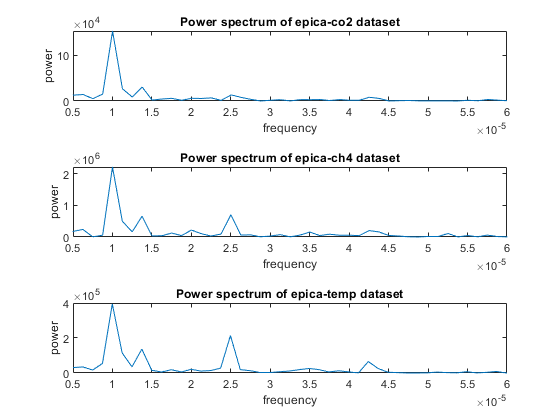

close all;

tiledlayout(3,1);

power_spectrum(obj_arr{1});
power_spectrum(obj_arr{2});
power_spectrum(obj_arr{3});

### plot S, A, B; G, a; H; P

close all;
Y = 100;
M = 50;
m = 5;
[a_final,N,f,P_final] = findanf_epica(epica_data,Y,M,m,1);

%%% trying my convergence idea thingy which didnt seem to work

% m = Y_est_round;
% 
% i = 1;
% close all;
% hold on;
% while i <= 15
%     
%     fprintf("iteration %d: m = %d\n",i,m);
%     
%     [a_final,~,~,~] = findanf_epica(epica_data,Y,M,m);
%     plot(a_final,'LineWidth',2);
%     int_a = sum(a_final) / M_length;
%     
%     T_a = 1 / abs(int_a);
%     num_M = T_a / M_length;
%     num_Y = num_M / M;
%     
%     if num_Y <= Y-2
%         m = round(num_Y);
%     else
%         m = Y - 2;
%     end
%     
%     i = i + 1;
% end
% legend("i=1","i=2","i=3","i=4","i=5","i=6","i=7","i=8","i=9","i=10");

### Running simulation

*for different values of m:*

close all;
Y = 200;
M = 50;

figure(1);
hold on;


% subtracted mean(yy) since that's what was used to center sim on zero!!!
plot(epica_data.X, epica_data.Y - mean(yy),"Color",[10 200 30]/255,'LineWidth',2);

m_arr = [2,5,10,50,100,150,190,198];
for m=m_arr
    disp(m);
    sim = epica_sim(epica_data,Y,M,m);
    sim_x = ( linspace(1,length(sim)+1,length(sim)) - length(sim) ) * 800000 / length(sim);
    [xx,yy] = interpolate(epica_data.X,epica_data.Y,Y*M,"makima");
    plot(sim_x,sim);
end

     2



     5



    10



    50



   100



   150



   190



   198



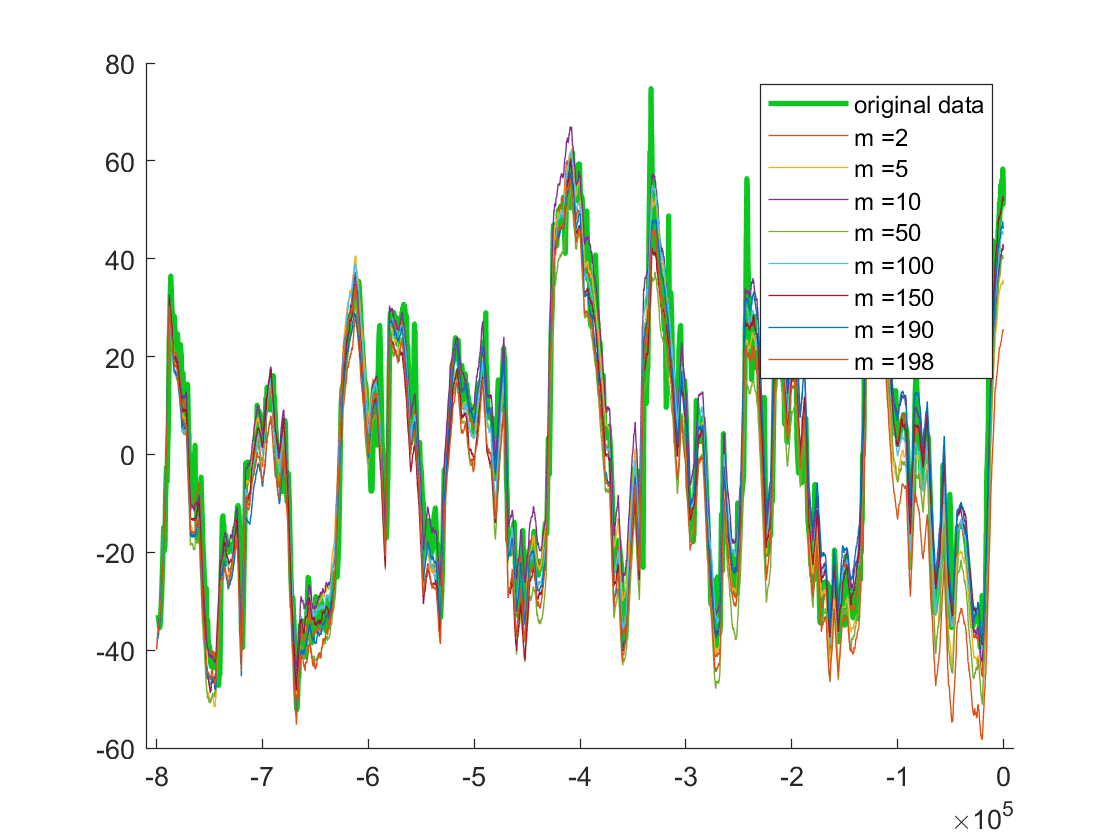


xlim([-810000,10000])
legend_cell = ["original data", strcat('m = ', string(num2cell(m_arr)))];
legend(legend_cell)

*for different values of Y:*

close all;

M = 50;
m = 5;


figure(2);
hold on;

% subtracted mean(yy) since that's what was used to center sim on zero!!!
plot(epica_data.X, epica_data.Y - mean(yy),"Color",[10 200 30]/255,'LineWidth',2);

Y_arr = [20,52,100];
for Y=Y_arr
    disp(Y);
    [sim_x,sim_y] = epica_sim(epica_data,Y,M,m);
    plot(sim_x,sim_y);
end

    20



    52



   100



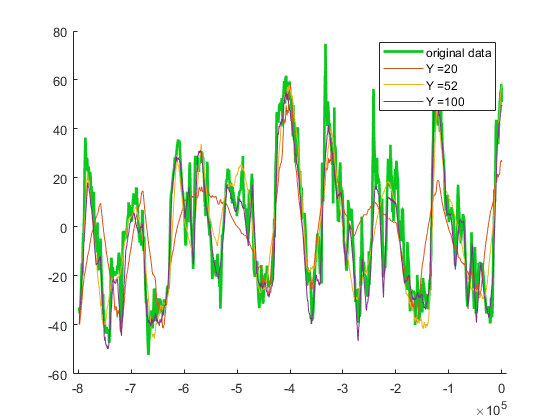


xlim([-810000,10000])
legend_cell = ["original data", strcat('Y = ', string(num2cell(Y_arr)))];
legend(legend_cell)

### Find statistics of data and simulation

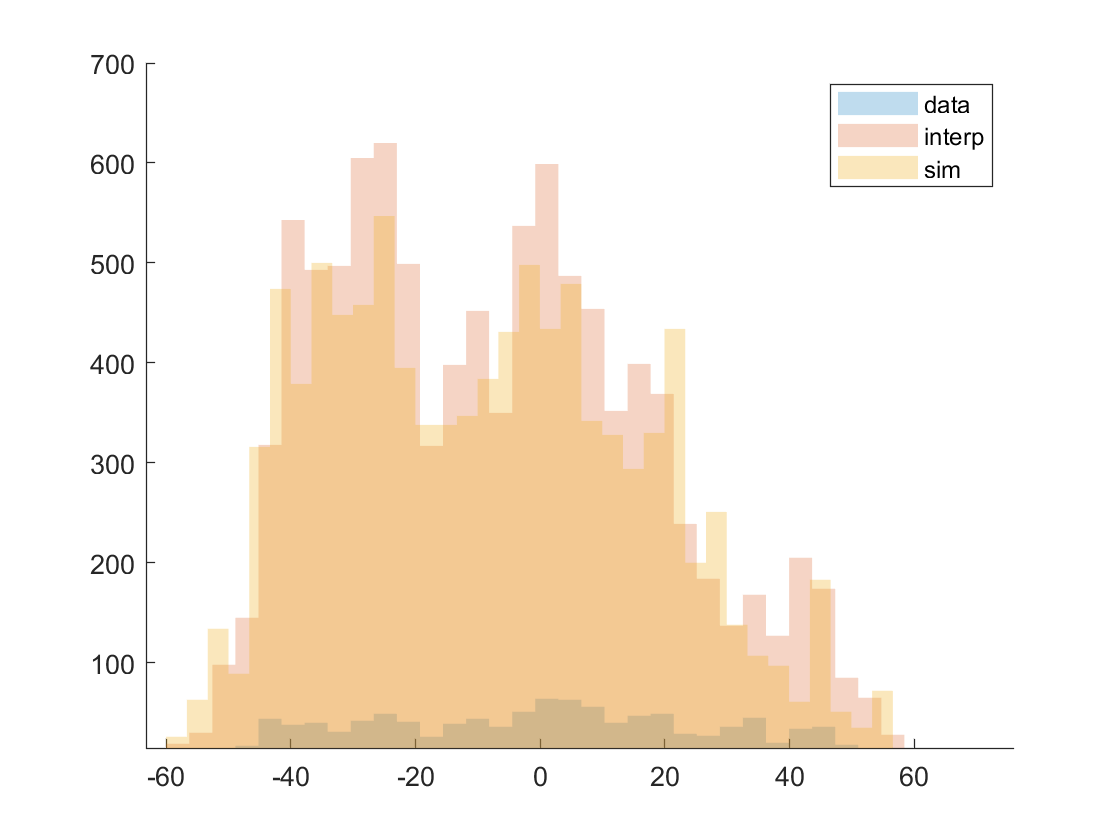

% stats on datasets
close all;
figure(1);
hold on;
histogram(epica_data.Y-mean(epica_data.Y),35,'FaceAlpha',0.25,'EdgeAlpha',0);
histogram(yy-mean(epica_data.Y),35,'FaceAlpha',0.25,'EdgeAlpha',0);
histogram(sim,35,'FaceAlpha',0.3,'EdgeAlpha',0);
legend("data","interp","sim");

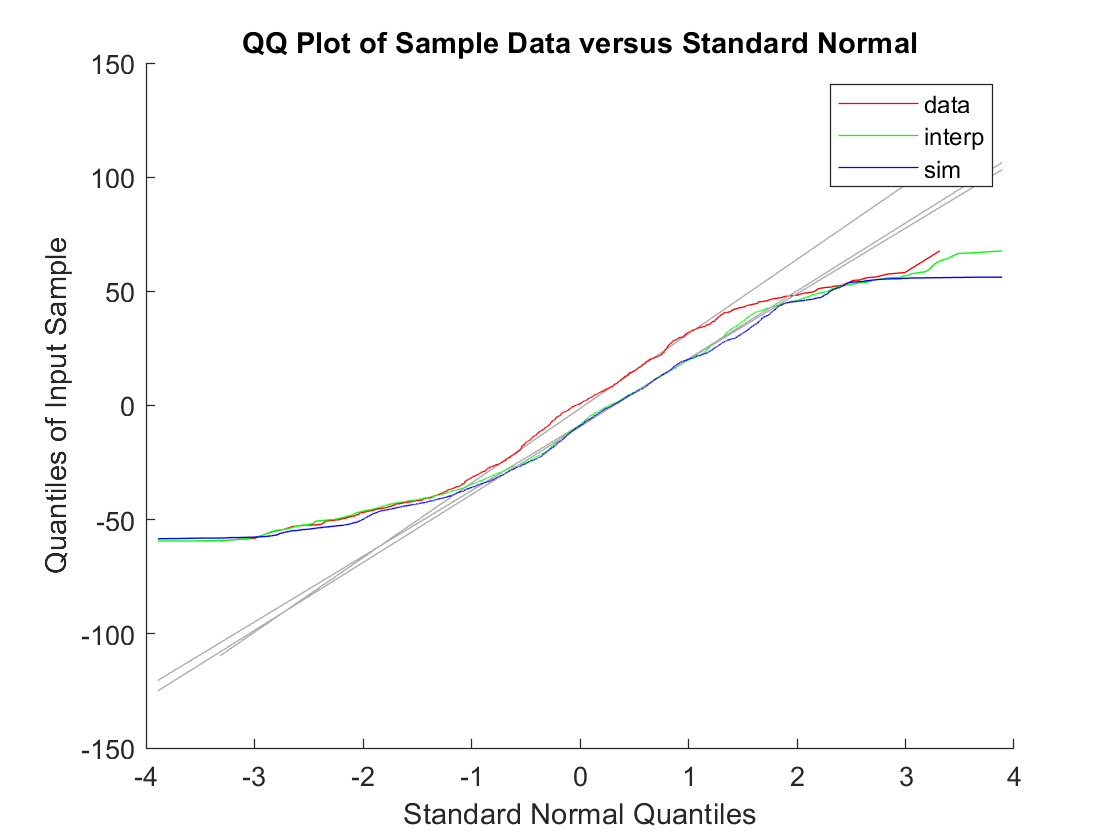


figure(2);
hold on;
% not sure abt this - subtracting mean(epica_data.Y) gives plot that looks
% right but isn't consistent with subtracting mean(yy) in previous section
h1 = qqplot(epica_data.Y-mean(epica_data.Y));
h2 = qqplot(yy-mean(epica_data.Y));
h3 = qqplot(sim);

set(h1(1),'LineStyle','-','Marker','none','Color','red');
set(h2(1),'LineStyle','-','Marker','none','Color','green');
set(h3(1),'LineStyle','-','Marker','none','Color','blue');

set(h1(2),'LineStyle','-','Color','#AAAAAA');
set(h2(2),'LineStyle','-','Color','#AAAAAA');
set(h3(2),'LineStyle','-','Color','#AAAAAA');

set(h1(3),'LineStyle','-','Color','#AAAAAA');
set(h2(3),'LineStyle','-','Color','#AAAAAA');
set(h3(3),'LineStyle','-','Color','#AAAAAA');

legend([h1(1) h2(1) h3(1)], "data","interp","sim");

dsadf

close all;

Y_arr = [52,100,200];
M = 50;
m = 5;
hold on;

plot(epica_data.X,epica_data.Y-mean(epica_data.Y),'Color','k');

for Y=Y_arr
    disp(Y);
    [sim_x,sim] = epica_sim(epica_data,Y,M,m);
    [xx,yy] = interpolate(epica_data.X,epica_data.Y,Y*M,"makima");
    plot(sim_x,sim);
end

legend("data","52","100","200");

    52



   100



   200



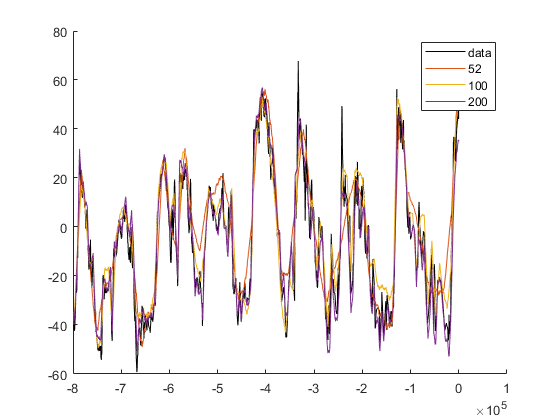

[sim_x,sim_y] = epica_sim(epica_data,52,50,5);

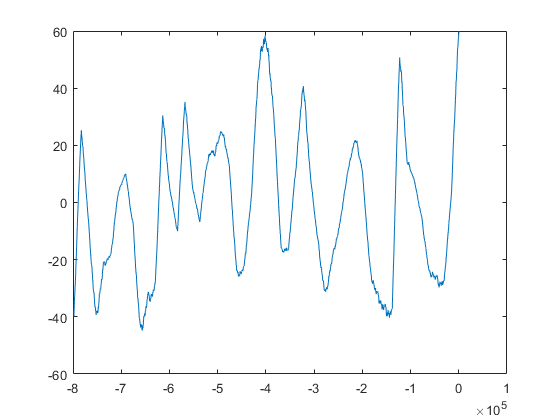

plot(sim_x,sim_y);